LAB 6

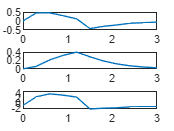

clear variables;

measured_data = importdata('TabelREGRESS.txt');
t = measured_data(:,1);
Vd = measured_data(:,2);
V = measured_data(:,3);
P = measured_data(:,4);

figure,
subplot(3,1,1), plot(t,Vd);
subplot(3,1,2), plot(t,V);
subplot(3,1,3), plot(t,P);

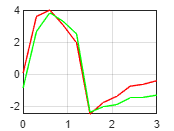


%Ptp = E*V + R*Vd

c = regress(P, [V Vd]);
E = c(1);
R = c(2);

Ptp = E * V + R * Vd;

figure, plot(t,Ptp,'r'),grid,hold on
plot(t, P, 'g')

%Ptp = E*V + R*Vd + P0 * y;
Y = ones(size(Vd));

c2 = regress(P, [V Vd Y]);
E1 = c2(1);
R1 = c2(2);
P0= c2(3);
hold off;

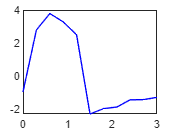

Ptp2 = E1 * V + R1 * Vd + P0 * Y;
figure,plot(t,Ptp2,'b')